% Ref_lane_C0=-0.5;Ref_lane_C1=0.05;Ref_lane_C2=0.0001;Ref_lane_C3=0.00001; %Ref_C1=-0.0069    Ref_C0=-1.5469
% %% 参考线离散化
% rz1 = [single(0):single(1):single(9)]
% rz2 = [single(10):20:150];
% rz = cat(2,rz1,rz2);   %为了减小运算量，同时又不损失精度，设计了前10m的分辨率1m，10-100m为Dis_Interval分辨率。
% rx = Ref_lane_C0 + Ref_lane_C1 .* rz + Ref_lane_C2 .* (rz.^2) + Ref_lane_C3 .* (rz.^3);
% Ref_Param.Ref_C0 = Ref_lane_C0;
% Ref_Param.Ref_C1 = Ref_lane_C1;
% Ref_Param.Ref_C2 = Ref_lane_C2;
% Ref_Param.Ref_C3 = Ref_lane_C3;
% 
% GenerateTargetCourse = @(wx, wy) calcSplineCourse(wx, wy,0.5); % calcSplineCourse(wx, wy, ds)
% [Ref_Spline,objSpline] = GenerateTargetCourse(rx, rz)
% Ref_Spline.rk
% Ref_Spline.rdk

A = [1;1;1]

A =      1
     1
     1


size(A,2)

ans = 1

B = [1;2;3]

B =      1
     2
     3


C = kron(A,B)

C =      1
     2
     3
     1
     2
     3
     1
     2
     3


D =sortrows(C,1)

D =      1
     1
     1
     2
     2
     2
     3
     3
     3


## 测试坐标转换

% [s_condition, d_condition] = cartesian_to_frenet3D(rs, rx, ry, rtheta, rkappa, rdkappa, x, y, v, a, theta, kappa)

% [x,y,v,θ,k,a]→[s,s˙,s¨,d,d′,d′′]

% rs = [0;0]; rx = [0.5;0.5]; ry=[0;0]; rtheta = [pi/4;pi/4]; rkappa = [0;0]; rdkappa = [0;0];
% x= [0;0]; y=[0;0]; v=5; a=[0;0]; theta=[pi/2;pi/2]; kappa = [0;0];

% rs = [0]; rx = [0.5]; ry=[0]; rtheta = [pi/2]; rkappa = [0]; rdkappa = [0];
% x= [0]; y=[0]; v=[5]; a=[0]; theta=[pi/2]; kappa = [0];
% 
% [s_condition, d_condition] = cartesian_to_frenet3D(rs, rx, ry, rtheta, rkappa, rdkappa, x, y, v, a, theta, kappa)
% [x, y, v, a, theta, kappa] = frenet_to_cartesian3D(rs, rx, ry, rtheta, rkappa, rdkappa, s_condition, d_condition)


% x = [0 0 0 0 0 0 0 0 0 0] 
% y= [ 0 1 2 3 4 5 6 7 8 9]

 x = [0 1 2 3 4 5 6 7 8 9] 

x =      0     1     2     3     4     5     6     7     8     9


 y=  [0 1 2 3 4 5 6 7 8 9]

y =      0     1     2     3     4     5     6     7     8     9


 
waypoints = [x' y']

waypoints =      0     0
     1     1
     2     2
     3     3
     4     4
     5     5
     6     6
     7     7
     8     8
     9     9



obj1 = FrenentReferencePath(waypoints,5)

obj1 =   FrenentReferencePath - 属性:

                PathPoints: [5×6 single]
    DiscretizationDistance: 3.1820
                 Waypoints: [10×2 double]


PP = obj1.PathPoints 

PP = 5×6 single 矩阵
         0         0    0.7854         0         0         0
    2.2500    2.2500    0.7854         0         0    3.1820
    4.5000    4.5000    0.7854         0         0    6.3640
    6.7500    6.7500    0.7854         0         0    9.5459
    9.0000    9.0000    0.7854         0         0   12.7279


globalStates = [8, 7, pi/4, 0, 1, 0]

globalStates =     8.0000    7.0000    0.7854         0    1.0000         0


frenetState = global2frenet(obj1, globalStates)

frenetState =    10.6066    1.0000         0   -0.7071   -0.0000         0


globalState = frenet2global(obj1, frenetState)

globalState = 1×6 single 行向量
    8.0000    7.0000    0.7854         0    1.0000         0


waypoints = [100 100; 150 200; 200 400]

waypoints =    100   100
   150   200
   200   400


referencePath = FrenentReferencePath(waypoints,20)

referencePath =   FrenentReferencePath - 属性:

                PathPoints: [20×6 single]
    DiscretizationDistance: 16.7347
                 Waypoints: [3×2 double]


Frenet_traj_obj = TrajectoryGeneratorFrenet(referencePath,0.5)

错误使用 TrajectoryGeneratorFrenet
输入参数太多。

arcLen = 0;
pathStart = referencePath.interpolate(arcLen)
vInit = 0;
aInit = 0;
initGlobalState = [pathStart(1:4) vInit aInit];
initFrenetState = global2frenet(referencePath, initGlobalState)
arcLenOffsets = [10; 20; 30];
lateralDeviation = [-5; 0; 5];

termFrenetStates_temp1 = sortrows(kron(ones(size(lateralDeviation,1),1),arcLenOffsets),1)
termFrenetStates_temp2 = kron(ones(size(lateralDeviation,1),1),lateralDeviation)
termFrenetStates = zeros(size(arcLenOffsets,1)*size(lateralDeviation,1),6)
termFrenetStates(:,[1 4]) = [termFrenetStates_temp1 termFrenetStates_temp2]




%termFrenetStates(:,[1 4]) = initFrenetState([1 4]) + [arcLenOffsets lateralDeviation]







timeSpanSingle = 10;

[frenetTrajectory,globalTrajectory] = Frenet_traj_obj.FrenetTrajectory(initFrenetState,termFrenetStates,timeSpanSingle)


TrajectoryGeneratorFrenet.TrajStateCombination(initFrenetState,arcLenOffsets,lateralDeviation,[5;10;15;20])





waypoints = [0 0;0 10; 0 20; 0 30;0 40;0 50;0 60;0 70;0 80;]
referencePath = FrenentReferencePath(waypoints,10)
arcLen = 0;
[pathStart pathStartID]= referencePath.interpolate(arcLen)
vInit = 15;
aInit = 0;
initGlobalState = [pathStart(1:4) vInit aInit]
%initGlobalState = [[0 0 1.5708 0] vInit aInit]
initFrenetState = referencePath.global2frenet(initGlobalState)
termFrenetStates = single(zeros(3,6));
arcLenOffsets = [50; 60; 70];
lateralDeviation = [-5; 0; 5];
timeSpan = [5;10];
FtNumTarpoints = 40;
Frenet_traj_obj = TrajectoryGeneratorFrenet(referencePath)
[frenetTrajectory,globalTrajectory] = Frenet_traj_obj.FrenetTrajectory(initFrenetState,arcLenOffsets,lateralDeviation,[10 0],[0 0],timeSpan,FtNumTarpoints)

[globalTrajectoryValid] = EvaluateTrajectory(frenetTrajectory,globalTrajectory, 5, 1, 1, 1)


clc
close all
for i =1 : size(globalTrajectory)
plot(globalTrajectory(i).Trajectory(:,1),globalTrajectory(i).Trajectory(:,2))
hold on
grid on
end
plot(globalTrajectoryValid(1).Trajectory(:,1),globalTrajectoryValid(1).Trajectory(:,2),"Color",'r',"LineWidth",5)

initialState = [0 0 pi/2]
[frenetTrajectory2,globalTrajectory2,numTraj] = Frenet_traj_obj.FrenetTrajectory_Lateral(initialState,arcLenOffsets,lateralDeviation,20,20)
for i =1 : size(globalTrajectory2)
plot(globalTrajectory2(i).Trajectory(:,1),globalTrajectory2(i).Trajectory(:,2),'*')
hold on
grid on
end


A0 = 3.5;A1=0.0007;A2=0.00007;A3=-3*(10)^-9;
rx1 = [single(0):single(1):single(9)];  
rx2 = [single(10):10:150];
rx = cat(2,rx1,rx2);
ry = single((-1)).*(A0 + A1.* rx + A2.* (rx.^2) + A3.* (rx.^3));
%创建路径点集合
waypoints = [ry',rx']; 
%通过函数FrenentReferencePath生成了一条基于路径点集合的平滑曲线referencePath
referencePath = FrenentReferencePath(waypoints,20);
pathStart = referencePath.interpolate(0);% 求起始点处车辆状态 [x, y,theta（弧度）, kappa（曲率）, dkappa（曲率变化率）, s（弧长）]

initialState = [0 -A0 pathStart(1,3)]   %初始状态

initialState = 1×3 single 行向量
         0   -3.5000    1.5715


Frenet_traj_obj = TrajectoryGeneratorFrenet(referencePath);
arcLenOffsets = single([90]);
VehSpeed = 35

VehSpeed = 35

% [frenetTrajectory3,globalTrajectory3,numTraj] = Frenet_traj_obj.FrenetTrajectory_Lateral(initialState,arcLenOffsets,[-3;0;3],20,20)
[frenetTrajectory3,globalTrajectory3,numTraj] = Frenet_traj_obj.FrenetTrajectory_Lateral(initialState,arcLenOffsets,0,40,40)

frenetTrajectory3 = 包含以下字段的 struct :
    Trajectory: [40×4 single]
             s: 90
             d: -4.7684e-07


globalTrajectory3 = 包含以下字段的 struct :
    Trajectory: [40×5 single]
         costs: 0


numTraj = 1

Temp1 = frenetTrajectory3.Trajectory(:,1)./VehSpeed;
AyDt = (diff(frenetTrajectory3.Trajectory(:,3).*(VehSpeed*VehSpeed)))./diff(Temp1)

AyDt = 39×1 single 列向量
   26.7353
    7.0175
    3.0886
   -0.1910
   -1.3391
   -1.9840
   -2.2553
   -2.3888
   -2.4468
   -2.4690


Temp2 = frenetTrajectory3.Trajectory(:,1)./VehSpeed;
AyDt2 = (diff(globalTrajectory3.Trajectory(:,4).*(VehSpeed*VehSpeed)))./diff(Temp2)

AyDt2 = 39×1 single 列向量
   27.1766
    4.6301
   12.1598
   -3.3171
   -6.1823
   -1.8588
   10.3992
  -16.7896
   -1.8327
    9.2014



[globalTrajectory4] = EvaluateTrajectory_Lateral(frenetTrajectory3,globalTrajectory3, 1,1)

globalTrajectory4 = 包含以下字段的 struct :
    Trajectory: [40×5 single]
         costs: 90


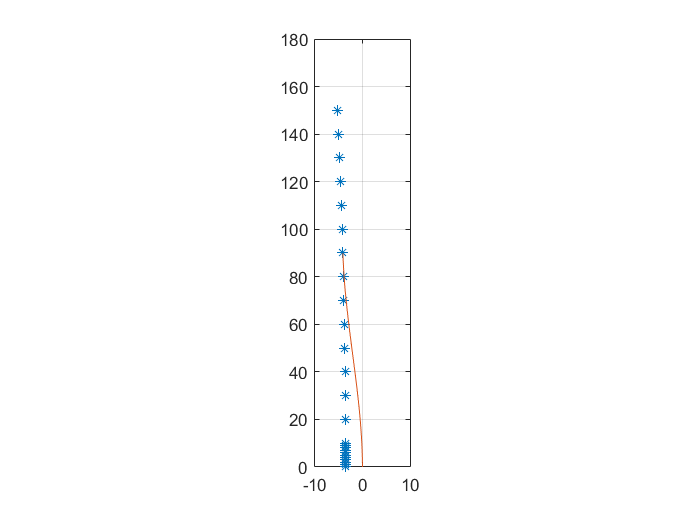

figure
plot(ry',rx','*')
Nx = 10;
Ny = 180;
axis([-10,Nx,0,Ny]);
set(gca,'DataAspectRatio',[1 2 1]);
hold on
grid on
plot(globalTrajectory4(1).Trajectory(:,1),globalTrajectory4(1).Trajectory(:,2))


matrix_state = Calc_State_Error(10,0,globalTrajectory4,0.3)

matrix_state = 6×1 single 列向量
    0.0154
   -0.1308
   -0.0131
   -0.0171
    4.6179
   -0.0163


referencePath =   FrenentReferencePath - 属性:

                PathPoints: [10×6 single]
    DiscretizationDistance: 16.6680
                 Waypoints: [25×2 single]


pathStart = 1×6 single 行向量
   -3.5000         0    1.5715    0.0000    0.0002         0


pathStartID = single
1

initGlobalState = 1×6 single 行向量
    1.5000         0    1.5715    0.0000   15.0000         0


initFrenetState = 1×6 single 行向量
         0   15.0000   -0.1991   -5.0000         0         0


Py = 1×17 single 行向量
   37.5000   40.5000   45.0000   49.5000   54.0000   60.0000   66.0000   72.0000   79.5000   87.0000   96.0000  106.5000  117.0000  129.0000  142.5000  156.0000  171.0000


Px = 1×17 single 行向量
   -3.6245   -3.6430   -3.6730   -3.7058   -3.7414   -3.7934   -3.8503   -3.9122   -3.9966   -4.0888   -4.2097   -4.3649   -4.5353   -4.7487   -5.0125   -5.3013   -5.6516


Frenet_traj_obj =   TrajectoryGeneratorFrenet - 属性:

    ReferencePath: [1×1 FrenentReferencePath]


Pl = single
40

Pt = single
3

pathend = 1×6 single 行向量
   -3.6444   39.9997    1.5771    0.0001   -0.0000   40.0000


endGlobalState = 1×6 single 行向量
   -3.6444   39.9997    1.5771    0.0001   15.0000         0


endFrenetState = 1×6 single 行向量
    40    15     0     0     0     0


frenetTrajectory = 包含以下字段的 struct :
    Trajectory: [40×6 single]
         Times: [40×1 single]
          jerk: [40×2 single]


globalTrajectory = 包含以下字段的 struct :
    Trajectory: [40×6 single]
         Times: [40×1 single]
         costs: 0


Pl = single
43

Pt = single
3

pathend = 1×6 single 行向量
   -3.6640   42.9996    1.5775    0.0001   -0.0000   43.0000


endGlobalState = 1×6 single 行向量
   -3.6640   42.9996    1.5775    0.0001   15.0000         0


endFrenetState = 1×6 single 行向量
   43.0000   15.0000         0   -0.0000         0         0


frenetTrajectory = 包含以下字段的 struct :
    Trajectory: [40×6 single]
         Times: [40×1 single]
          jerk: [40×2 single]


globalTrajectory = 包含以下字段的 struct :
    Trajectory: [40×6 single]
         Times: [40×1 single]
         costs: 0


Pl = single
47

Pt = single
3

pathend = 1×6 single 行向量
   -3.6901   46.9995    1.5781    0.0001   -0.0000   47.0000


endGlobalState = 1×6 single 行向量
   -3.6901   46.9995    1.5781    0.0001   15.0000         0


endFrenetState = 1×6 single 行向量
   47.0000   15.0000         0   -0.0000         0         0


frenetTrajectory = 包含以下字段的 struct :
    Trajectory: [40×6 single]
         Times: [40×1 single]
          jerk: [40×2 single]


globalTrajectory = 包含以下字段的 struct :
    Trajectory: [40×6 single]
         Times: [40×1 single]
         costs: 0


Pl = single
52

Pt = single
3

pathend = 1×6 single 行向量
   -3.7273   51.9994    1.5788    0.0001   -0.0000   52.0000


endGlobalState = 1×6 single 行向量
   -3.7273   51.9994    1.5788    0.0001   15.0000         0


endFrenetState = 1×6 single 行向量
    52    15     0     0     0     0


frenetTrajectory = 包含以下字段的 struct :
    Trajectory: [40×6 single]
         Times: [40×1 single]
          jerk: [40×2 single]


globalTrajectory = 包含以下字段的 struct :
    Trajectory: [40×6 single]
         Times: [40×1 single]
         costs: 0


Pl = single
57

Pt = single
4

pathend = 1×6 single 行向量
   -3.7715   56.9992    1.5794    0.0001   -0.0000   57.0000


endGlobalState = 1×6 single 行向量
   -3.7715   56.9992    1.5794    0.0001   15.0000         0


endFrenetState = 1×6 single 行向量
   57.0000   15.0000         0   -0.0000         0         0


frenetTrajectory = 包含以下字段的 struct :
    Trajectory: [40×6 single]
         Times: [40×1 single]
          jerk: [40×2 single]


globalTrajectory = 包含以下字段的 struct :
    Trajectory: [40×6 single]
         Times: [40×1 single]
         costs: 0


Pl = single
63

Pt = single
4

pathend = 1×6 single 行向量
   -3.8245   62.9990    1.5803    0.0001   -0.0000   63.0000


endGlobalState = 1×6 single 行向量
   -3.8245   62.9990    1.5803    0.0001   15.0000         0


endFrenetState = 1×6 single 行向量
   63.0000   15.0000         0    0.0000         0         0


frenetTrajectory = 包含以下字段的 struct :
    Trajectory: [40×6 single]
         Times: [40×1 single]
          jerk: [40×2 single]


globalTrajectory = 包含以下字段的 struct :
    Trajectory: [40×6 single]
         Times: [40×1 single]
         costs: 0


Pl = single
69

Pt = single
5

pathend = 1×6 single 行向量
   -3.8829   68.9987    1.5811    0.0001   -0.0000   69.0000


endGlobalState = 1×6 single 行向量
   -3.8829   68.9987    1.5811    0.0001   15.0000         0


endFrenetState = 1×6 single 行向量
    69    15     0     0     0     0


frenetTrajectory = 包含以下字段的 struct :
    Trajectory: [40×6 single]
         Times: [40×1 single]
          jerk: [40×2 single]


globalTrajectory = 包含以下字段的 struct :
    Trajectory: [40×6 single]
         Times: [40×1 single]
         costs: 0


Num = 7

globalTrajectoryValid = 包含以下字段的 struct :
    Trajectory: [40×6 single]
         Times: [40×1 single]
         costs: 78.6606


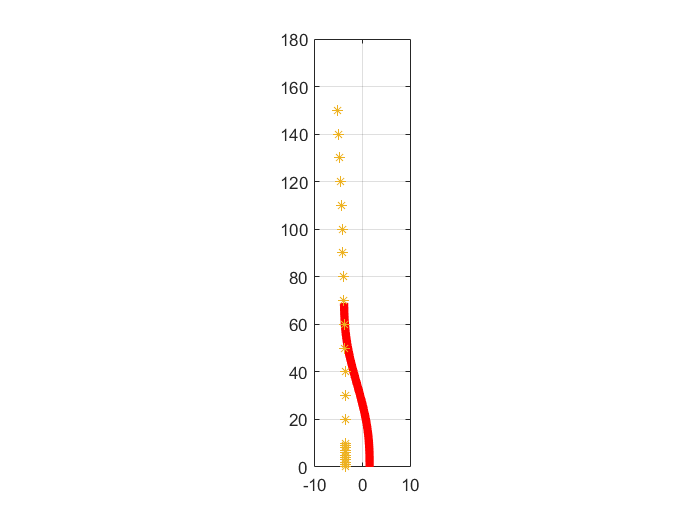

A0 = 3.5;A1=0.0007;A2=0.00007;A3=-3*(10)^-9;

rx1 = [single(0):single(1):single(9)];  
rx2 = [single(10):10:150];
rx = cat(2,rx1,rx2);
ry = single((-1)).*(A0 + A1.* rx + A2.* (rx.^2) + A3.* (rx.^3));
waypoints = [ry',rx'];
% waypoints = [0 0;0 10; 0 20; 0 30;0 40;0 50;0 60;0 70;0 80;]
referencePath = FrenentReferencePath(waypoints,10)
arcLen = 0;
[pathStart pathStartID]= referencePath.interpolate(arcLen)
vInit = 15;
aInit = 0;
initGlobalState = [1.5 pathStart(2:4) vInit aInit]
initFrenetState = referencePath.global2frenet(initGlobalState)
%
vEgo = 15;
Py =single([2.5	2.7	3 3.3 3.6 4 4.4	4.8	5.3	5.8	6.4	7.1	7.8	8.6	9.5 10.4 11.4]);
TarEgoAy = zeros(1,length(Py));
TarEgoV = ones(1,length(Py)) .* vEgo;
Py = vEgo.*Py
Px = single((-1)).*(A3.*(Py.^3) + A2.*(Py.^2) + A1.*(Py.^1) + A0)
Frenet_traj_obj = TrajectoryGeneratorFrenet(referencePath)
FtNumTarpoints = 40;
%1:length(Px)
for i = 1:length(Px)
    Pl = round(1.05*sqrt(Px(i)^2 + Py(i)^2))
    Pt = round(1.05*sqrt(Px(i)^2 + Py(i)^2)/max(1,0.5*(TarEgoV(i) + vEgo)))
    % 计算终点期望横向加速度 lPrimePrime 公式：lDotDot = lPrimePrime * sDot^2 + lPrime*sDotDot
    % lDotDot = TarEgoV(i)*TarEgoV(i)*(single((-1))*(6*A3*Py(i) + 2*A2))
    % lPrimePrime = lDotDot/(TarEgoV(i)*TarEgoV(i))
    pathend= referencePath.interpolate(Pl)
    endGlobalState = [pathend(1:4) TarEgoV(i) TarEgoAy(i)]
    endFrenetState = referencePath.global2frenet(endGlobalState)
    
    [frenetTrajectory,globalTrajectory] = Frenet_traj_obj.FrenetTrajectory(initFrenetState,endFrenetState(1,1),0,endFrenetState(1,2:3),endFrenetState(1,5:6),Pt,FtNumTarpoints)
    % Temp = diff((frenetTrajectory.Trajectory(:,3)).*(frenetTrajectory.Trajectory(:,6)))./diff(globalTrajectory.Times)
    AyDt = abs(diff(globalTrajectory.Trajectory(:,4).*((globalTrajectory.Trajectory(:,5).^2)))./diff(globalTrajectory.Times));
    if all(abs(AyDt)<3.5)
        break;
    end
end

Num = i
[globalTrajectoryValid] = EvaluateTrajectory(frenetTrajectory,globalTrajectory, 5, 1, 1, 1)


clc
close all
for i =1 : size(globalTrajectory)
plot(globalTrajectory(i).Trajectory(:,1),globalTrajectory(i).Trajectory(:,2))
Nx = 10;
Ny = 180;
axis([-10,Nx,0,Ny]);
set(gca,'DataAspectRatio',[1 2 1]);
hold on
grid on
end
plot(globalTrajectoryValid(1).Trajectory(:,1),globalTrajectoryValid(1).Trajectory(:,2),"Color",'r',"LineWidth",5)
plot(ry',rx','*')

% initialState = [0 -3.5 pi/2]
% [frenetTrajectory2,globalTrajectory2,numTraj] = Frenet_traj_obj.FrenetTrajectory_Lateral(initialState,arcLenOffsets,lateralDeviation,20,20)
% for i =1 : size(globalTrajectory2)
% plot(globalTrajectory2(i).Trajectory(:,1),globalTrajectory2(i).Trajectory(:,2),'*')
% hold on
% grid on
% end

%% 查规划线弯曲BUG
A0 = 0.0673;A1=0.00378;A2=-0.0033;A3=-0.000045;
rx1 = [single(0):single(1):single(9)];  
rx2 = [single(10):10:150];
rx = cat(2,rx1,rx2);
ry = single((-1)).*(A0 + A1.* rx + A2.* (rx.^2) + A3.* (rx.^3));
waypoints = [ry',rx'];
% waypoints = [0 0;0 10; 0 20; 0 30;0 40;0 50;0 60;0 70;0 80;]]
Veh_Speed = 40/3.6;
referencePath = FrenentReferencePath(waypoints,120);
initGlobalState = [0 0 pi/2 0 Veh_Speed  0]; %暂时定义纵向加速度为0，[x, y,theta, kappa speed，Acc]
initFrenetState = referencePath.global2frenet(initGlobalState);
Py =single([1.5 2 2.5 3 3.6 4.2 5 5.8 6.4 7	7.8	8.6	9.5 10.4 11.4]);
TarEgoAy = zeros(1,length(Py));% 终点处期望纵向加速度
TarEgoV = ones(1,length(Py)) .* Veh_Speed;% 终点处期望纵向速度
Py = max(Veh_Speed,5).*Py;
Px = single((-1)).*(A3.*(Py.^3) + A2.*(Py.^2) + A1.*(Py.^1) + A0);

Frenet_traj_obj = TrajectoryGeneratorFrenet(referencePath);
FtNumTarpoints = 20;
%% 生成轨迹
for i = 1:length(Py)
    Pl = round(1.05*sqrt(Px(i)^2 + Py(i)^2));
    Pt = round(1.05*sqrt(Px(i)^2 + Py(i)^2)/max(1,0.5*(TarEgoV(i) + Veh_Speed)));
    pathend= referencePath.interpolate(Pl);
    EndGlobalState = [pathend(1:4) TarEgoV(i) TarEgoAy(i)];
    EndFrenetState = referencePath.global2frenet(EndGlobalState);
    [frenetTrajectory,globalTrajectory] = Frenet_traj_obj.FrenetTrajectory(initFrenetState,EndFrenetState(1,1),0,EndFrenetState(1,2:3),EndFrenetState(1,5:6),Pt,FtNumTarpoints);
    AyDt = abs(diff(globalTrajectory.Trajectory(:,4).*((globalTrajectory.Trajectory(:,5).^2)))./diff(globalTrajectory.Times));
    if all(abs(AyDt)<5)
        break;
    end
end

Num = i

Num = 1

[globalTrajectoryValid] = EvaluateTrajectory(frenetTrajectory,globalTrajectory, 5, 1, 1, 1)

globalTrajectoryValid = 包含以下字段的 struct :
    Trajectory: [20×6 single]
         Times: [20×1 single]
         costs: 4.9847e+03


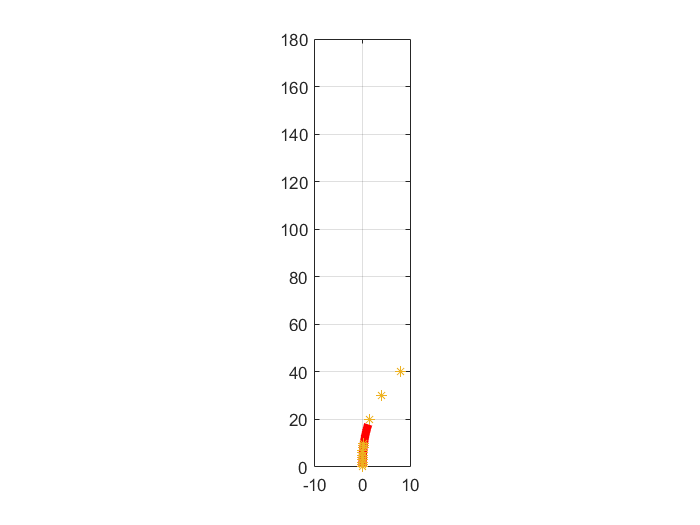



clc
close all
for i =1 : size(globalTrajectory)
plot(globalTrajectory(i).Trajectory(:,1),globalTrajectory(i).Trajectory(:,2))
Nx = 10;
Ny = 180;
axis([-10,Nx,0,Ny]);
set(gca,'DataAspectRatio',[1 2 1]);
hold on
grid on
end
plot(globalTrajectoryValid(1).Trajectory(:,1),globalTrajectoryValid(1).Trajectory(:,2),"Color",'r',"LineWidth",5)
plot(ry',rx','*')

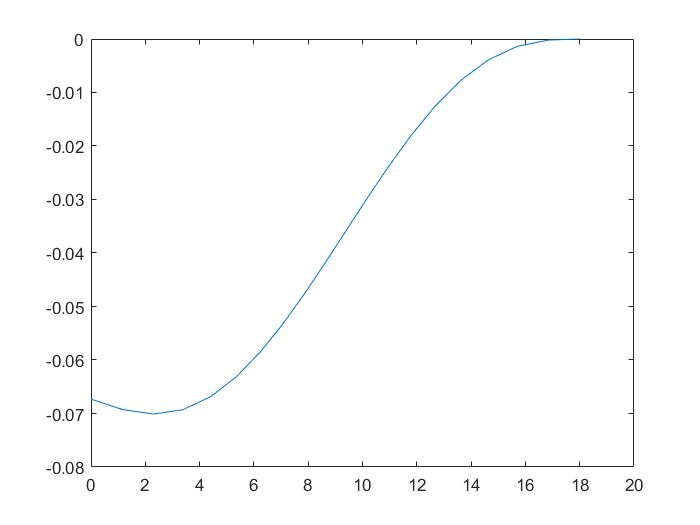

figure
plot(frenetTrajectory(1).Trajectory(:,1),frenetTrajectory(1).Trajectory(:,4))